# Q1 Investigation

Live script designed to replicate Axle side of Q1Q2Investigation

We will come at the problem from 2 angles:

- First, we solve the problem using the typical equations in Annex C of SIA 269

- Second, we perform tail fitting and try to use return period to get the design value

- Finally, we compare the two methods

% Initial commands
clear, clc, close all
% This function loads the variable 'AxTandem' which is produced by 'AxleStatsBasic'
load('AxTandem.mat')


### Step 1: Input desired filters/parameters

% Select which year to analyze
Years = 0;
%Years = 2011:2019;

% Select stations (locations) to analyze
Stations = 0;
%Stations = [408 409 405 406 402 415 416];

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassType = {'All', 'ClassOW', 'Class'};
ClassT = {'All', 'Classified+', 'Classified'};


### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = AxTandem.ZST == Stations;
    AxTandem(~any(y,2),:) = [];
end
if Years > 0
    y = year(AxTandem.Time) == Years;
    AxTandem(~any(y,2),:) = [];
end


### Step 3: Build Structure with Block Maxima

% Transform AxTandem into Array (necessary for splitapply)
Z = AxTandem;
Z.Time = datenum(Z.Time);
Z = table2array(Z);
            
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Filter based on Class - AxTandem is compromised after this (deleting entries)
    if strcmp(Class,'ClassOW')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
    elseif strcmp(Class,'Class')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
        AxTandem(AxTandem.CLASS > 39 & AxTandem.CLASS < 50,:) = [];
        Z(Z(:,5) > 39 & Z(:,5) < 50,:) = [];
    end
      
    for j = 1:length(BM)
        BlockM = BM{j};
        
        % Initialize
        Max.(Class).(BlockM) = [];
        
        if strcmp(BlockM,'Daily')
            
            % Make groups out of unique locations and days
            [Gr, GrIDDay, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','day'),AxTandem.ZST);
            
        elseif strcmp(BlockM,'Weekly')
            
            [Gr, GrIDWeek, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','week'),AxTandem.ZST);
            
        else
            
            [Gr, GrIDYear, GrIDZST] = findgroups(year(AxTandem.Time),AxTandem.ZST);
            
        end
        
        % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
        Max.(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
        % Transform back into table form
        Max.(Class).(BlockM) = array2table(Max.(Class).(BlockM));
        Max.(Class).(BlockM).Properties.VariableNames = {'Max','AWT1kN','AWT2kN','W1_2M','ZST','CLASS','Time'};
        Max.(Class).(BlockM).Time = datetime(Max.(Class).(BlockM).Time,'ConvertFrom',"datenum");
        
    end  
end


#### Curve Fitting

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:1:800;

% Fit Block Maxima to Normal Curve
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        for k = 1:length(DistTypes)
            Dist = DistTypes{k};
   
            pd.(Class).(BlockM).(Dist) = fitdist(Max.(Class).(BlockM).Max/2,Dist);
            y_values.(Class).(BlockM).(Dist).PDF_Fit = pdf(pd.(Class).(BlockM).(Dist),x_values);
            y_values.(Class).(BlockM).(Dist).CDF_Fit = cdf(pd.(Class).(BlockM).(Dist),x_values);
            
            if strcmp(BlockM,'Daily')
                y_values.(Class).('Weekly').(Dist).CDF_D2W = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                y_values.(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values.(Class).('Weekly').(Dist).CDF_D2W)];
                y_values.(Class).('Yearly').(Dist).CDF_D2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_D2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                end

            elseif strcmp(BlockM,'Weekly')
                y_values.(Class).('Yearly').(Dist).CDF_W2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_W2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                end
                
            end
        end
    end
end


### Step 4: Plot Block Maxima

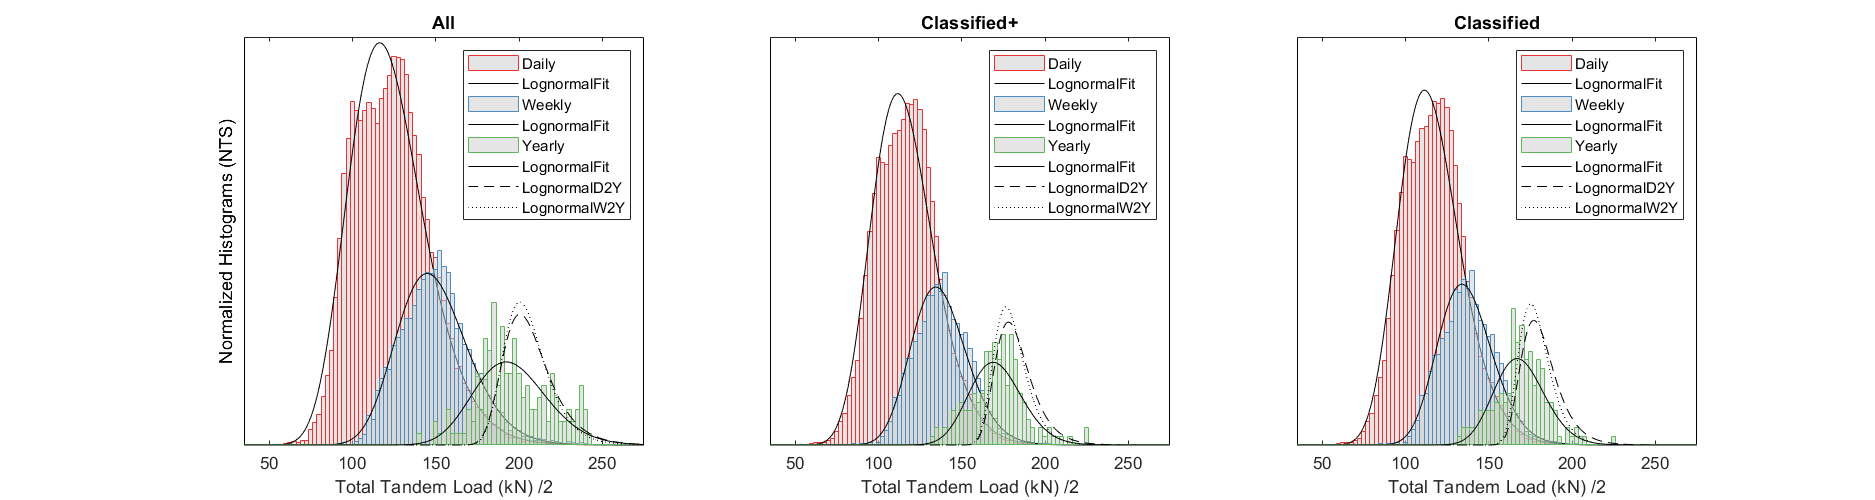

figure('Position',[0 0 1500 400]);

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 2.5;
LimitL = 10;
LimitR = 300;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).Max/2,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
            
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Tandem Load (kN) /2')
    title([ClassT{i}])
    legend('location','northeast')
    
end

#### *Block Maxima Compared between each other*

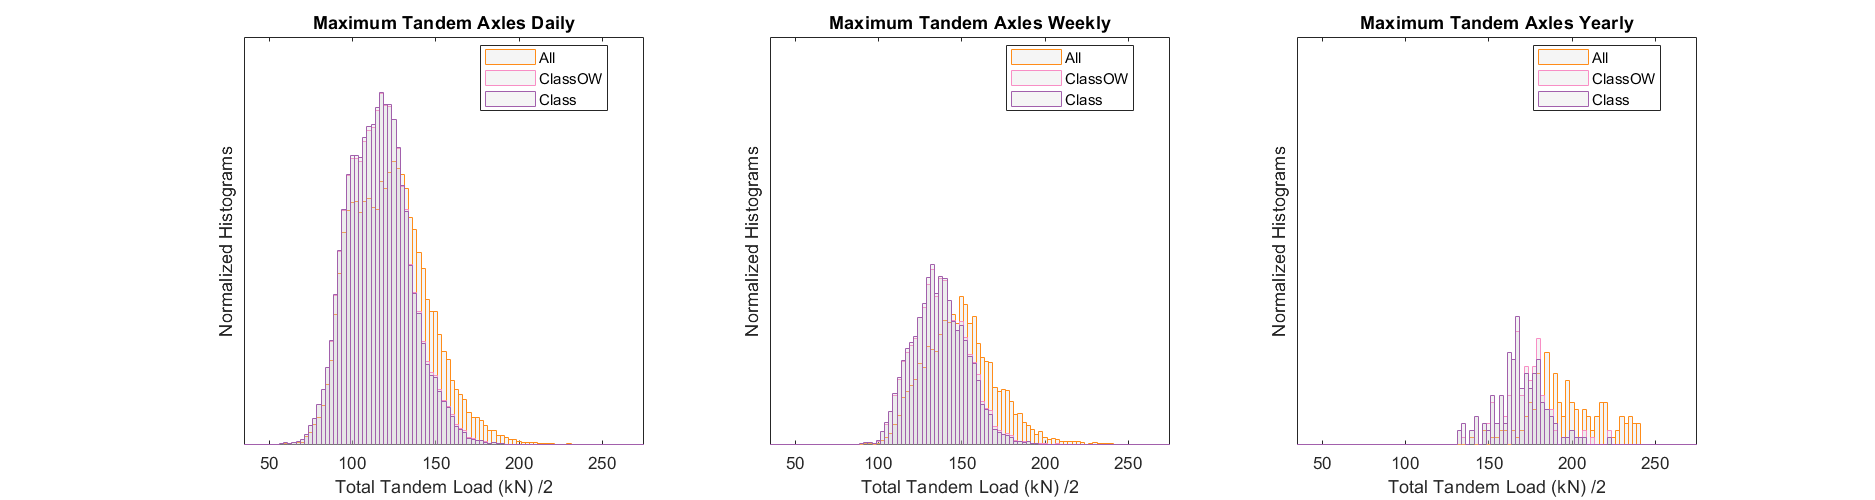

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 2.5;
LimitL = 10;
LimitR = 300;
Xp = LimitL-Step/2:Step:LimitR-Step/2;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    
    histogram(Max.All.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(4,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','All')
    histogram(Max.ClassOW.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(7,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','ClassOW')
    histogram(Max.Class.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(9,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','Class')
    
    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    ylabel('Normalized Histograms')
    xlabel('Total Tandem Load (kN) /2')
    title(['Maximum Tandem Axles ' BlockM])
    legend('location','best')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

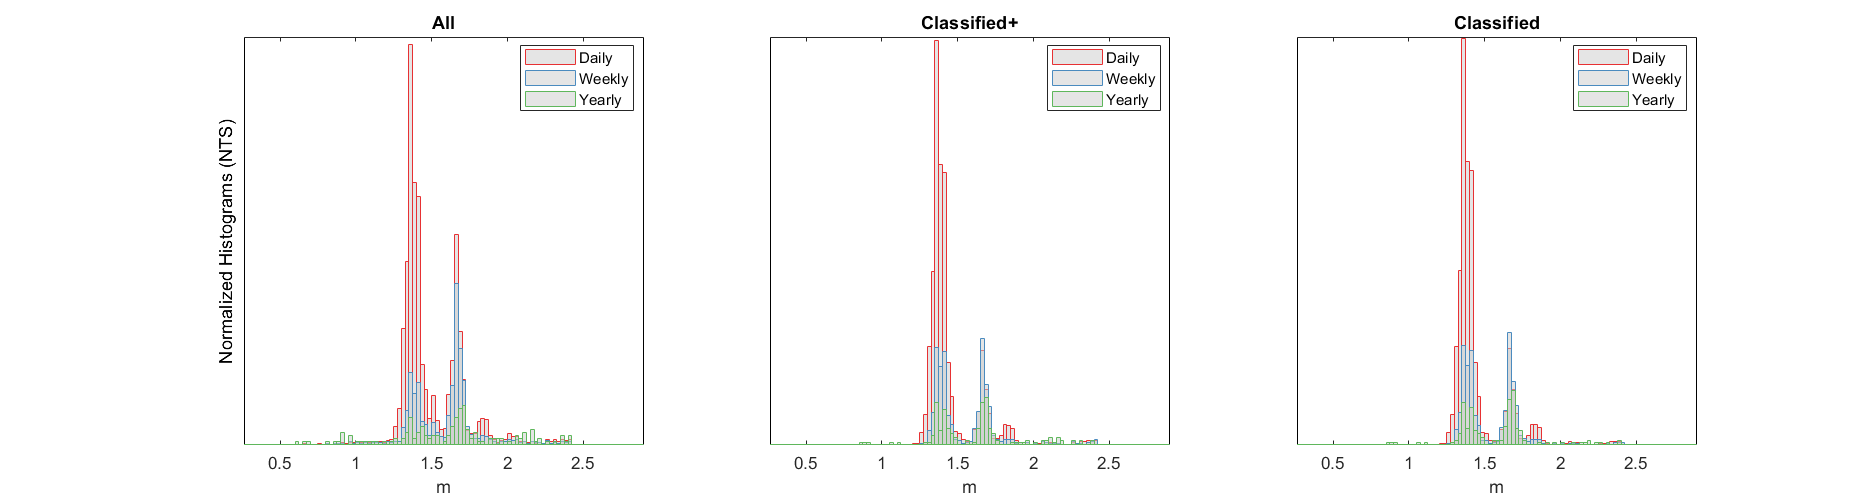

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 0.025;
LimitL = Step/2;
LimitR = 3.15;
X = LimitL:Step:LimitR;
Xp = LimitL-Step/2:Step:LimitR-Step/2;
x = X(1:end-1) + diff(X);

for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).W1_2M,'BinEdges',X,'normalization','pdf');
        if i == 2 & strcmp(BlockM,"Weekly")
            ystar = Max.(Class).(BlockM).W1_2M;
        end
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+.25 LimitR-.25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('m')
    title([ClassT{i}])
    legend('location','best')
    %xticks(0.4:0.2:2.6)
end

#### *Axle Spacing (of Maxima) Comparison*

% The next step is to compute alpha values... we can compare these to those
% in the memo from the last OFROU mtg


### Step 5: Summarize $\alpha_Q$ Estimates


% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;

% Right now we assume a normal distribution in the Edact calculation. Also
% perform for lognormal.

% Initialize SumTable
SumTableNorm = array2table(zeros(6,length(BM)*length(ClassType)));
SumTableLogNormComp = array2table(zeros(5,length(BM)*length(ClassType)));
SumTableNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], [BM{2} ' ' ClassType{3}],...
    [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{1}], [BM{1} ' ' ClassType{3}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{1}]};
SumTableLogNorm = SumTableNorm;
SumTableNorm.Properties.RowNames = {'Mu', 'Sigma', 'COV (%)', '95th %', 'Dist 95', 'AlphaQ'};
SumTableLogNorm.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQN', 'AlphaQLN'};
SumTableLogNormComp.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQLN Est'};
SumTableLogNormComp.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], ['W2Y ' ClassType{3}],...
    ['W2Y ' ClassType{2}], ['W2Y ' ClassType{1}], ['D2Y ' ClassType{3}], ['D2Y ' ClassType{2}], ['D2Y ' ClassType{1}]};

for i = 1:length(ClassType)
    Class = ClassType{i};

    for j = 1:length(BM)
        BlockM = BM{j};
            
        Emact = mean(Max.(Class).(BlockM).Max/2);
        Stdev = std(Max.(Class).(BlockM).Max/2);
        COV = Stdev/Emact;
        Delta2 = log(COV^2+1);
        N5 = prctile(Max.(Class).(BlockM).Max/2,95);     
        Dist95N = norminv(0.95,pd.(Class).(BlockM).Normal.mu,pd.(Class).(BlockM).Normal.sigma);
        Dist95LN = logninv(0.95,pd.(Class).(BlockM).Lognormal.mu,pd.(Class).(BlockM).Lognormal.sigma);

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

        
        EdactN = Emact*(1+Alpha*Beta.(BlockM)*COV);
        AlphaQN = EdactN/(300*1.5);

               Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
               ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Mu            169.10           171.05          195.90         136.84           137.44          149.52        115.97          116.20         122.82  
    Sigma          15.07            15.94           21.92          16.41            16.73           21.66         18.50           18.71          23.18  
    COV (%)         8.91      

        EdactLN = Emact*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);

                Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
                ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Lambda           5.13             5.14            5.27           4.91             4.92            5.00          4.74            4.74           4.79  
    Zeta             0.09             0.09            0.11           0.12             0.12            0.14          0.16            0.16           0.19  
    95th %         195.27 

        AlphaQLN = EdactLN/(300*1.5);

                    Yearly Class    Yearly ClassOW    Yearly All    W2Y Class    W2Y ClassOW    W2Y All    D2Y Class    D2Y ClassOW    D2Y All
                    ____________    ______________    __________    _________    ___________    _______    _________    ___________    _______

    Lambda               5.13             5.14            5.27         5.18          5.19         5.32        5.20          5.20         5.33 
    Zeta                 0.09             0.09            0.11         0.06          0.06         0.07        0.07          0.07         0.08 
    95th %             195.27           200.74          235.65       1


        SumTableNorm.([BlockM ' ' Class]) = [Emact; Stdev; 100*COV; N5; Dist95N; AlphaQN];
        SumTableLogNorm.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQN; AlphaQLN];
        
        if strcmp(BlockM,'Weekly')
            pdx = pd.(Class).W2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['W2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max/2,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        elseif strcmp(BlockM,'Daily')
            pdx = pd.(Class).D2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['D2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max/2,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        else
            SumTableLogNormComp.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQLN];
        end

    end
end

format bank 
disp(SumTableNorm)
disp(SumTableLogNorm)
disp(SumTableLogNormComp)

### Step 6: Probability Paper Plotting & Tail Fitting Methods

When we apply the above equations, we are assuming the maximums are normally or log-normally distributed. We should evaluate the fit with a probability paper plot.

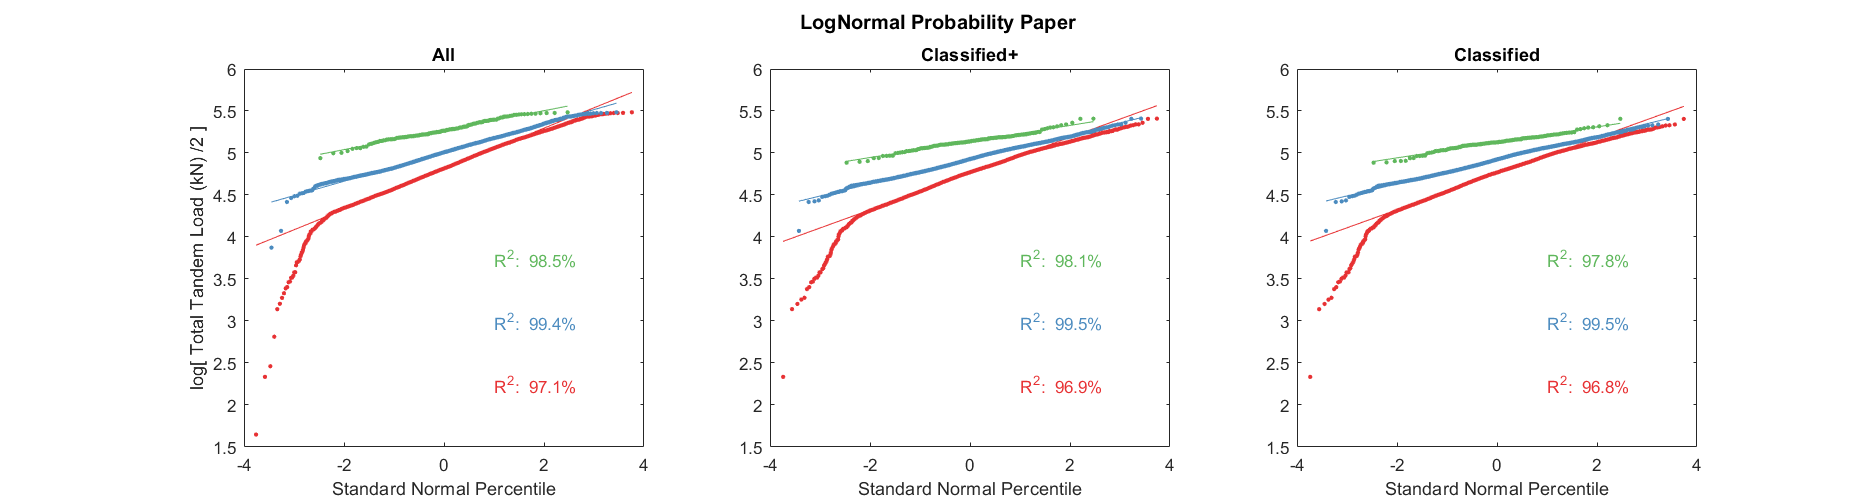

figure('Position',[0 0 1500 400]);

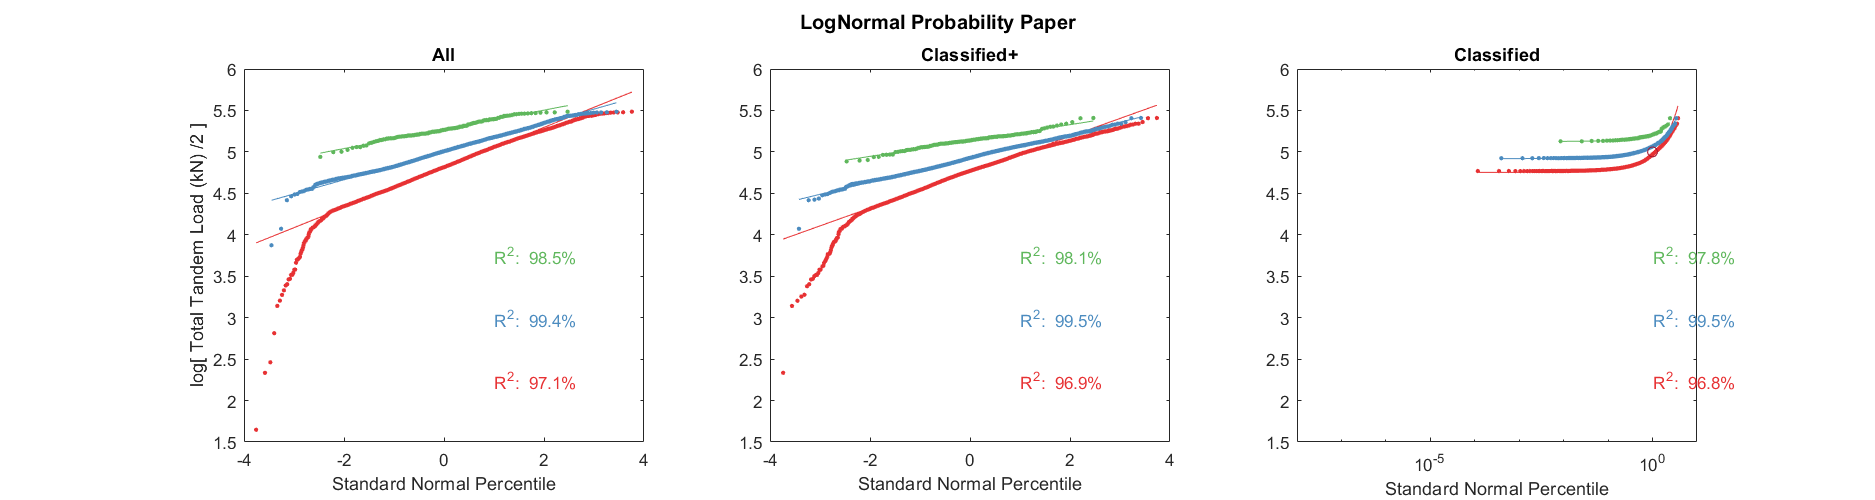

   
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    
    for j = 1:length(BM)
        BlockM = BM{j};
        subplot(1,3,i)
        hold on
        
        [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max/2); MaxECDFRank = MaxECDFRank';  MaxECDF(1) = []; MaxECDFRank(1) = [];
        
        scatter(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),7,C(j,:),'filled','DisplayName','Max Data');
        mdl = fitlm(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),log(MaxECDFRank),'linear');
        
        plot(norminv((1:length(MaxECDFRank))/(length(MaxECDFRank) + 1)),mdl.Fitted,'-','Color',C(j,:),'DisplayName',['Fitted ' num2str(mdl.Rsquared.Ordinary,3)]);
        
        
        %text(1,y1(1)+(y1(2)-y1(1))/j,['\lambda = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(1)) '\zeta = ' sprintf('%.2f \n',mdl.Coefficients.Estimate(2)) sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100)])
        
        

        box on
        xlim([-4 4])
        ylim([1.5 6])
        y1 = ylim;
        
        text(1,y1(1)+(y1(2)-y1(1))*(j/6),sprintf('R^2:  %.1f%%',mdl.Rsquared.Ordinary*100),"Color",C(j,:))
        

        
        
    end
    
        
    if i == 1
        ylabel('log[ Total Tandem Load (kN) /2 ]')
    end
    xlabel('Standard Normal Percentile')
    

    title([ClassT{i}])
    
end

sgtitle('LogNormal Probability Paper','fontweight','bold','fontsize',12);

% Try with Gumbel Probability Paper

% for i = 1:length(ClassType)
%     Class = ClassType{i};
%     figure('Position',[0 0 1500 400]);
%     
%     for j = 1:length(BM)
%         BlockM = BM{j};
%         subplot(1,3,j)
%         hold on
%         
%         [MaxECDF, MaxECDFRank] = ecdf(Max.(Class).(BlockM).Max/2); MaxECDFRank = MaxECDFRank';
%         
%         scatter(MaxECDFRank,-log(-log(MaxECDF)),7,'k','filled','DisplayName','Max Data');
% 
%         box on
%         
%         ylabel('-log(-log(Probability of non-exceedance))')
%         xlabel('Total Tandem Load (kN) /2')
%         legend('location','best')
%         
%         title(['Maximum Tandem Axles ' BlockM])
%     end
% 
%     sgtitle(['Gumbel Probability Paper - ' Class ' Axles'],'fontweight','bold','fontsize',12);
%     
% end


Reproducing Figure 3-3 from JRC Background Document to EN 1991 Part 2


Q = 5:10:245;
AllAx = [AxTandem.AWT1kN; AxTandem.AWT2kN];

AllAx(AllAx < 5) = [];
xQ = sum(AllAx > Q)./length(AllAx);
scatter(xQ,Q)
set(gca, 'XScale', 'log')
xlim([10^-8 10])

#### Try Capping axle loads at 18 and 21t to see the result on the alpha factors...

% This function loads the variable 'AxTandem' which is produced by 'AxleStatsBasic'
load('AxTandem.mat')


### Step 1: Input desired filters/parameters

% Select which year to analyze
Years = 0;
%Years = 2011:2019;

% Select stations (locations) to analyze
Stations = 0;
%Stations = [408 409 405 406 402 415 416];

% Block Maxima (always use j)
BM = {'Daily', 'Weekly', 'Yearly'};

% Select which Classification you want to analyze (always use i)
% Must be in the order 'All' 'ClassOW' 'Class' due to deletions
ClassType = {'All', 'ClassOW', 'Class'};
ClassT = {'All', 'Classified+', 'Classified'};


### Step 2: Filter Axles based on desired year and station (location)

% Filter Axles based on desired year and station (location)
if Stations > 0
    y = AxTandem.ZST == Stations;
    AxTandem(~any(y,2),:) = [];
end
if Years > 0
    y = year(AxTandem.Time) == Years;
    AxTandem(~any(y,2),:) = [];
end
% CAPPING
y = AxTandem.AWT1kN > 176.5197;
AxTandem(y,:) = [];
y = AxTandem.AWT2kN > 176.5197;
AxTandem(y,:) = [];

### Step 3: Build Structure with Block Maxima

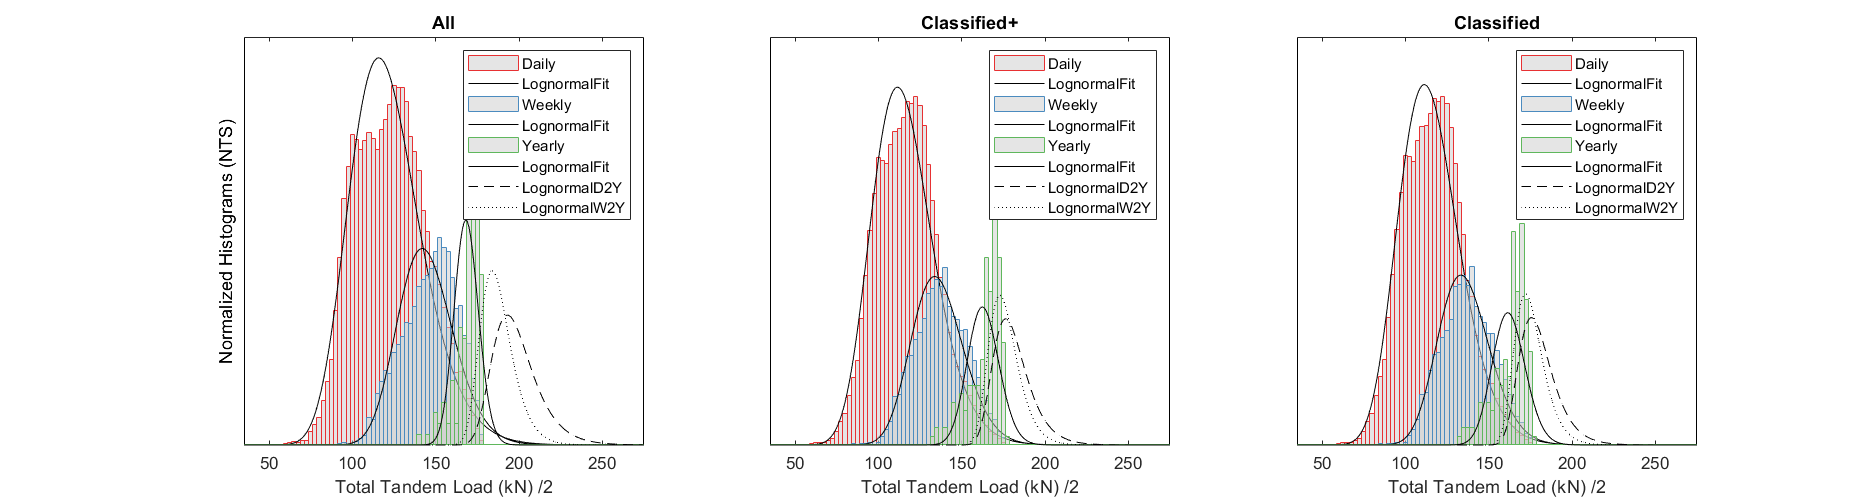

% Transform AxTandem into Array (necessary for splitapply)
Z = AxTandem;
Z.Time = datenum(Z.Time);
Z = table2array(Z);
            
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    % Filter based on Class - AxTandem is compromised after this (deleting entries)
    if strcmp(Class,'ClassOW')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
    elseif strcmp(Class,'Class')
        AxTandem(AxTandem.CLASS == 0,:) = [];
        Z(Z(:,5) == 0,:) = [];
        AxTandem(AxTandem.CLASS > 39 & AxTandem.CLASS < 50,:) = [];
        Z(Z(:,5) > 39 & Z(:,5) < 50,:) = [];
    end
      
    for j = 1:length(BM)
        BlockM = BM{j};
        
        % Initialize
        Max.(Class).(BlockM) = [];
        
        if strcmp(BlockM,'Daily')
            
            % Make groups out of unique locations and days
            [Gr, GrIDDay, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','day'),AxTandem.ZST);
            
        elseif strcmp(BlockM,'Weekly')
            
            [Gr, GrIDWeek, GrIDZST] = findgroups(dateshift(AxTandem.Time,'start','week'),AxTandem.ZST);
            
        else
            
            [Gr, GrIDYear, GrIDZST] = findgroups(year(AxTandem.Time),AxTandem.ZST);
            

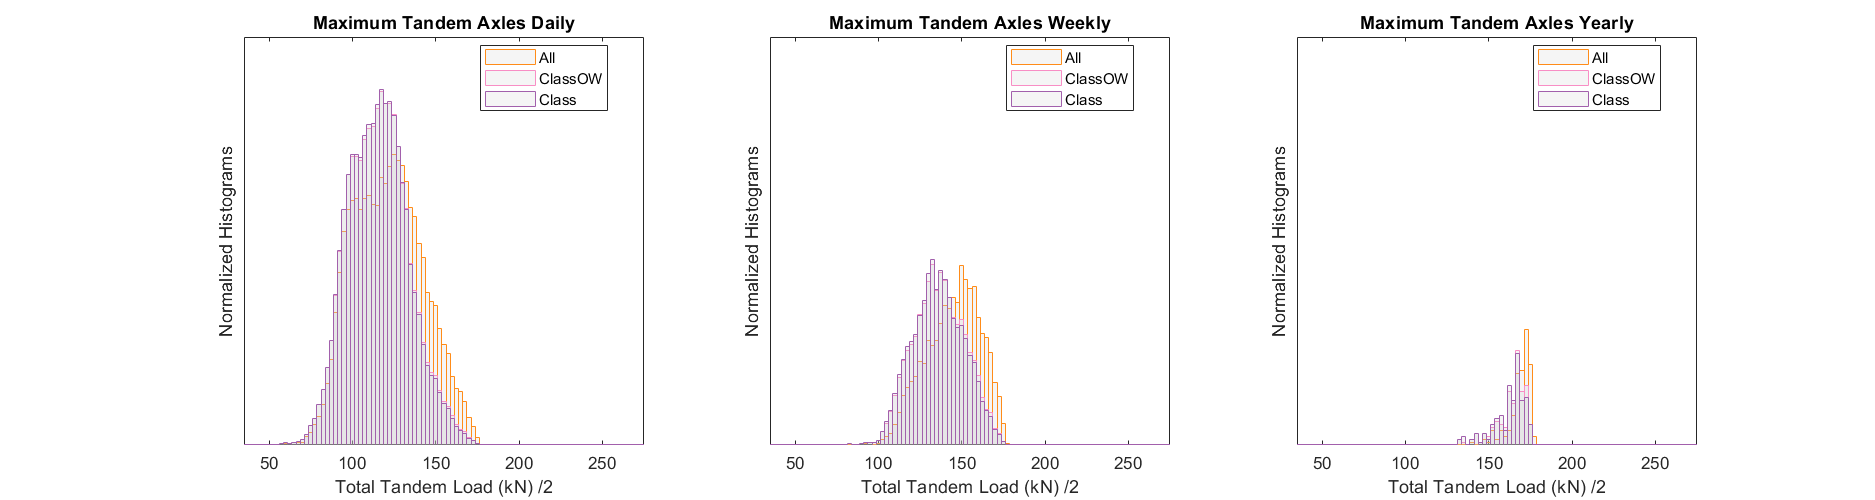

        end
        
        % Perform splitapply (see function at end... not just Max as we want whole rows involving maxes)
        Max.(Class).(BlockM) = splitapply(@(Z)maxIndex(Z),Z,Gr);
        % Transform back into table form
        Max.(Class).(BlockM) = array2table(Max.(Class).(BlockM));
        Max.(Class).(BlockM).Properties.VariableNames = {'Max','AWT1kN','AWT2kN','W1_2M','ZST','CLASS','Time'};
        Max.(Class).(BlockM).Time = datetime(Max.(Class).(BlockM).Time,'ConvertFrom',"datenum");
        
    end  
end


#### Curve Fitting

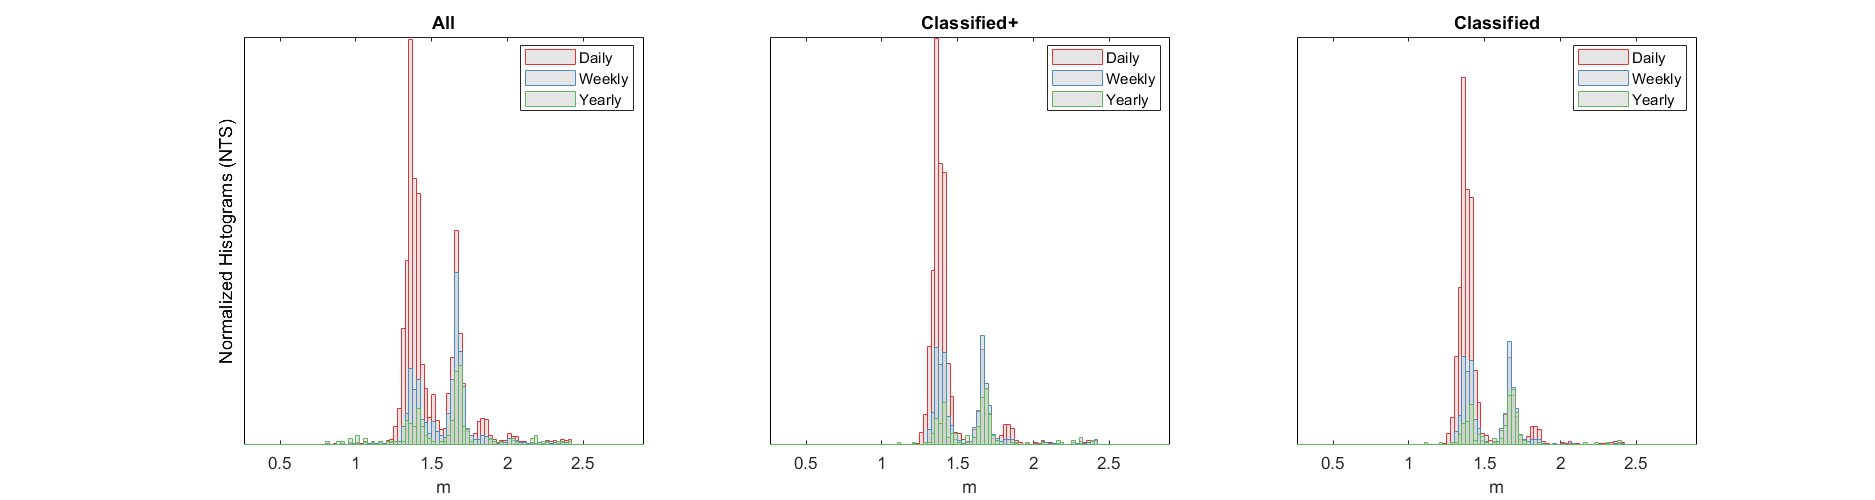

% Set Distribution Types
DistTypes = {'Normal', 'Lognormal', 'GeneralizedExtremeValue'};

% Set CDF Scaling Factors for estimates
D2WFactor = 5; W2YFactor = 50; D2YFactor = D2WFactor*W2YFactor;

% Set x values to be use globally
x_values = 0:1:800;

% Fit Block Maxima to Normal Curve
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        for k = 1:length(DistTypes)
            Dist = DistTypes{k};
   
            pd.(Class).(BlockM).(Dist) = fitdist(Max.(Class).(BlockM).Max/2,Dist);
            y_values.(Class).(BlockM).(Dist).PDF_Fit = pdf(pd.(Class).(BlockM).(Dist),x_values);
            y_values.(Class).(BlockM).(Dist).CDF_Fit = cdf(pd.(Class).(BlockM).(Dist),x_values);
            
            if strcmp(BlockM,'Daily')
                y_values.(Class).('Weekly').(Dist).CDF_D2W = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2WFactor;
                y_values.(Class).('Weekly').(Dist).PDF_D2W = [0 diff(y_values.(Class).('Weekly').(Dist).CDF_D2W)];
                y_values.(Class).('Yearly').(Dist).CDF_D2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^D2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_D2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_D2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Weekly').(Dist).CDF_D2W,(x_values-mu).^2));

                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2W.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_D2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).D2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                end

            elseif strcmp(BlockM,'Weekly')
                y_values.(Class).('Yearly').(Dist).CDF_W2Y = y_values.(Class).(BlockM).(Dist).CDF_Fit.^W2YFactor;
                y_values.(Class).('Yearly').(Dist).PDF_W2Y = [0 diff(y_values.(Class).('Yearly').(Dist).CDF_W2Y)];
                
                if strcmp(Dist,'Normal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",mu,"sigma",sigma);
                    
                elseif strcmp(Dist,'Lognormal')
                    mu = trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,x_values);
                    sigma = sqrt(trapz(y_values.(Class).('Yearly').(Dist).CDF_W2Y,(x_values-mu).^2));
                    zeta = sqrt(log(1+(sigma/mu)^2));
                    lambda = log(mu)-0.5*zeta^2;
                    pd.(Class).W2Y.(Dist) = makedist(Dist,"mu",lambda,"sigma",zeta);
                    
                end
                
            end
        end
    end
end


### Step 4: Plot Block Maxima

figure('Position',[0 0 1500 400]);


               Yearly Class    Yearly ClassOW    Yearly All    Weekly Class    Weekly ClassOW    Weekly All    Daily Class    Daily ClassOW    Daily All
               ____________    ______________    __________    ____________    ______________    __________    ___________    _____________    _________

    Mu            162.35           163.21          168.59         135.96           136.41          144.80        115.69          115.89         121.44  
    Sigma           9.48             9.08            6.98          15.29            15.41           16.13         18.06           18.21          20.99  
    COV (%)         5.84      

% Set colours
C = linspecer(9);
% ScaleDown
ScaleDown = [1 2.5 5];
% X Stuff
Step = 2.5;
LimitL = 10;
LimitR = 300;
X = LimitL:Step:LimitR;
x = X(1:end-1) + diff(X);
    
for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).Max/2,'BinEdges',X,'normalization','pdf');
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
        for k = 2
            Dist = DistTypes{k};
       
            plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_Fit/ScaleDown(j),'k-','DisplayName',[Dist 'Fit'])
            
            if strcmp(BlockM,'Yearly')
                
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_D2Y/ScaleDown(j),'k--','DisplayName',[Dist 'D2Y'])
                plot(x_values,y_values.(Class).(BlockM).(Dist).PDF_W2Y/ScaleDown(j),'k:','DisplayName',[Dist 'W2Y'])
            end
            
        end
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+25 LimitR-25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('Total Tandem Load (kN) /2')
    title([ClassT{i}])
    legend('location','northeast')
    
end

#### *Block Maxima Compared between each other*

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 2.5;
LimitL = 10;
LimitR = 300;
Xp = LimitL-Step/2:Step:LimitR-Step/2;

for j = 1:length(BM)
    BlockM = BM{j};
    
    subplot(1,3,j)
    hold on
    
    histogram(Max.All.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(4,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','All')
    histogram(Max.ClassOW.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(7,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','ClassOW')
    histogram(Max.Class.(BlockM).Max/2,'BinEdges',Xp,'normalization','pdf','EdgeColor',C(9,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.2,'DisplayName','Class')
    
    % Set Plot Details
    a = ylim;
    ylim([a(1) a(2)*j])
    box on
    set(gca,'ytick',[],'yticklabel',[])
    ylabel('Normalized Histograms')
    xlabel('Total Tandem Load (kN) /2')
    title(['Maximum Tandem Axles ' BlockM])
    legend('location','best')
    xlim([LimitL+25 LimitR-25])
    
end

#### *Block Maxima Compared for Classification Filters*

figure('Position',[0 0 1500 400]);

% X Stuff
Step = 0.025;
LimitL = Step/2;
LimitR = 3.15;
X = LimitL:Step:LimitR;
Xp = LimitL-Step/2:Step:LimitR-Step/2;
x = X(1:end-1) + diff(X);

for i = 1:length(ClassType)
    Class = ClassType{i};
    
    subplot(1,3,i)
    hold on
    
    for j = 1:length(BM)
        BlockM = BM{j};
        
        y = histcounts(Max.(Class).(BlockM).W1_2M,'BinEdges',X,'normalization','pdf');
        if i == 2 & strcmp(BlockM,"Weekly")
            ystar = Max.(Class).(BlockM).W1_2M;
        end
        bar(x,y/ScaleDown(j),1,'EdgeColor',C(j,:),'FaceColor',[.8 .8 .8],'FaceAlpha',0.5,'DisplayName',BlockM)
        
    end
    
    % Set Plot Details
    set(gca,'ytick',[],'yticklabel',[],'ycolor','k')
    box on
    xlim([LimitL+.25 LimitR-.25])
    if i == 1
        ylabel('Normalized Histograms (NTS)')
    end
    xlabel('m')
    title([ClassT{i}])
    legend('location','best')
    %xticks(0.4:0.2:2.6)
end

#### *Axle Spacing (of Maxima) Comparison*

% The next step is to compute alpha values... we can compare these to those
% in the memo from the last OFROU mtg


### Step 5: Summarize $\alpha_Q$ Estimates


% According to Annex C of SIA 269
Beta.Yearly = 4.7; % Here we use the Beta annual - so we should use annual max effects
Beta.Weekly = 5.44422; % See Tail Fitting > Beta Conversion
Beta.Daily = 5.72397;
Alpha = 0.7;

% Right now we assume a normal distribution in the Edact calculation. Also
% perform for lognormal.

% Initialize SumTable
SumTableNorm = array2table(zeros(6,length(BM)*length(ClassType)));
SumTableLogNormComp = array2table(zeros(5,length(BM)*length(ClassType)));
SumTableNorm.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], [BM{2} ' ' ClassType{3}],...
    [BM{2} ' ' ClassType{2}], [BM{2} ' ' ClassType{1}], [BM{1} ' ' ClassType{3}], [BM{1} ' ' ClassType{2}], [BM{1} ' ' ClassType{1}]};
SumTableLogNorm = SumTableNorm;
SumTableNorm.Properties.RowNames = {'Mu', 'Sigma', 'COV (%)', '95th %', 'Dist 95', 'AlphaQ'};
SumTableLogNorm.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQN', 'AlphaQLN'};
SumTableLogNormComp.Properties.RowNames = {'Lambda', 'Zeta', '95th %', 'Dist 95', 'AlphaQLN Est'};
SumTableLogNormComp.Properties.VariableNames = {[BM{3} ' ' ClassType{3}], [BM{3} ' ' ClassType{2}], [BM{3} ' ' ClassType{1}], ['W2Y ' ClassType{3}],...
    ['W2Y ' ClassType{2}], ['W2Y ' ClassType{1}], ['D2Y ' ClassType{3}], ['D2Y ' ClassType{2}], ['D2Y ' ClassType{1}]};

for i = 1:length(ClassType)
    Class = ClassType{i};

    for j = 1:length(BM)
        BlockM = BM{j};
            
        Emact = mean(Max.(Class).(BlockM).Max/2);
        Stdev = std(Max.(Class).(BlockM).Max/2);
        COV = Stdev/Emact;
        Delta2 = log(COV^2+1);
        N5 = prctile(Max.(Class).(BlockM).Max/2,95);     
        Dist95N = norminv(0.95,pd.(Class).(BlockM).Normal.mu,pd.(Class).(BlockM).Normal.sigma);
        Dist95LN = logninv(0.95,pd.(Class).(BlockM).Lognormal.mu,pd.(Class).(BlockM).Lognormal.sigma);

*We account for the fact that the reliability index, *$\beta$, *must be for the same reference period as *$E_{m,\textrm{act}}$

Normal Distribution:                            $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \left\lbrack 1+\alpha \beta \nu \right\rbrack$

Lognormal Distribution:                      $E_{d,\textrm{act}} =E_{m,\textrm{act}} \cdot \exp \left\lbrack \alpha \beta \delta -0\ldotp 5\delta^2 \right\rbrack$      where         $\delta^2 =\ln \left(\nu^2 +1\right)$

        
        EdactN = Emact*(1+Alpha*Beta.(BlockM)*COV);
        AlphaQN = EdactN/(300*1.5);
        EdactLN = Emact*exp(Alpha*Beta.(BlockM)*sqrt(Delta2)-0.5*Delta2);
        AlphaQLN = EdactLN/(300*1.5);

        SumTableNorm.([BlockM ' ' Class]) = [Emact; Stdev; 100*COV; N5; Dist95N; AlphaQN];
        SumTableLogNorm.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQN; AlphaQLN];
        
        if strcmp(BlockM,'Weekly')
            pdx = pd.(Class).W2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['W2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max/2,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        elseif strcmp(BlockM,'Daily')
            pdx = pd.(Class).D2Y.Lognormal;
            Delta2 = pdx.sigma^2;
            Emact = exp(pdx.mu+0.5*Delta2);
            SumTableLogNormComp.(['D2Y ' Class]) = [pdx.mu; pdx.sigma; prctile(Max.(Class).Yearly.Max/2,95); logninv(0.95,pdx.mu,pdx.sigma); Emact*exp(Alpha*Beta.Yearly*sqrt(Delta2)-0.5*Delta2)/(300*1.5)];
        else
            SumTableLogNormComp.([BlockM ' ' Class]) = [pd.(Class).(BlockM).Lognormal.mu; pd.(Class).(BlockM).Lognormal.sigma; N5; Dist95LN; AlphaQLN];
        end

    end
end

format bank 
disp(SumTableNorm)

#### Function(s)

function out = maxIndex(Z)
    [ymax, loc]=max(sum([Z(:,1) Z(:,2)],2));
    out=[ymax, Z(loc,:)];
end